## Problem 1

**Using the tight-binding model, compute the energy band formed by atomic s-orbitals in a square lattice of constant *****a*****, with a single atom basis (the s-level atomic energy and the overlap integrals, respectively) are considered to be known).**

**a) Plot the energy band **$(\epsilon_q \space\text{versus} \spaceq )$** in 3D.**

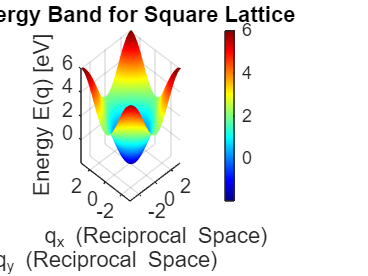

clc
clear
close all

qx = linspace(-pi, pi, 100);  % k_x space
qy = linspace(-pi, pi, 100);  % k_y space

% I searched for typical values for Es and gamma in different papers
% From what I remember in class, gamma is negative
Es = 2; % eV
gamma = -1; % eV

[QX, QY] = meshgrid(qx, qy);

E_k = Es + 2*gamma * cos(QX) + 2*gamma * cos(QY);

figure;
surf(QX, QY, E_k, 'EdgeColor', 'none');  % 3D surface plot
xlabel('q_x (Reciprocal Space)', 'FontSize', 12);
ylabel('q_y (Reciprocal Space)', 'FontSize', 12);
zlabel('Energy E(q) [eV]', 'FontSize', 12);
title('Energy Band for Square Lattice', 'FontSize', 20);
colormap jet;
colorbar;
grid on;
view([-45, 30]); % Adjust viewing angle for better visualization
set(gca, 'FontSize', 12);